# **RS-WISP-01: Geo-Stationary Orbit Generation**

**WorkerInSpace Senior Researcher**

**Hongseok Kim**

**1/14/2025**

## **I. Scope**

  Review of the two-Body Model and generate LEO parking orbit, Geo-Transfer Orbit and GEO Stational Orbit

Starting from two-body model


$$\ddot{\mathit{\mathbf{r}}} =-\mu \frac{\vec{\mathit{\mathbf{r}}} }{{\left|\vec{\mathit{\mathbf{r}}} \right|}^3 }$$


## **II. Satellite Initial Orbit Parameter and Simulation Parameter Setting**

clear; clc;

Tsim = 86400;
delt = 1;
N = floor(Tsim/delt);
tVec = [0:N-1]' * delt;


%% Define Initial Time
initial_epoch = posixtime(datetime('2024-03-21 00:00:00'));


elapsed_days = 0;
%% Define Current time
current_epoch = initial_epoch + elapsed_days * 24 * 3600;
epoch_datetime = datetime(current_epoch + tVec,'ConvertFrom','posixtime','Format','MM/dd/uuuu HH:mm:ss');
epoch = [epoch_datetime.Year, epoch_datetime.Month, epoch_datetime.Day, epoch_datetime.Hour, epoch_datetime.Minute, epoch_datetime.Second];
disp(epoch_datetime(1))

   03/21/2024 00:00:00




% Orbit Contstant
J2 = 0.00108248;
R_Earth = 6378.1363;
mu = 398600.4415;


%% Speed at Apoapsis
vel_aps = zeros(5,1);


%% Define Initial Orbit Parameter
SMA = 24434.864; 
ecc = 0.728693;
inc = 0;
RAAN = 0;
AOP = 0;
theta = 180;
orbit_period = 2*pi* sqrt(SMA^3/mu)

orbit_period = 3.8012e+04

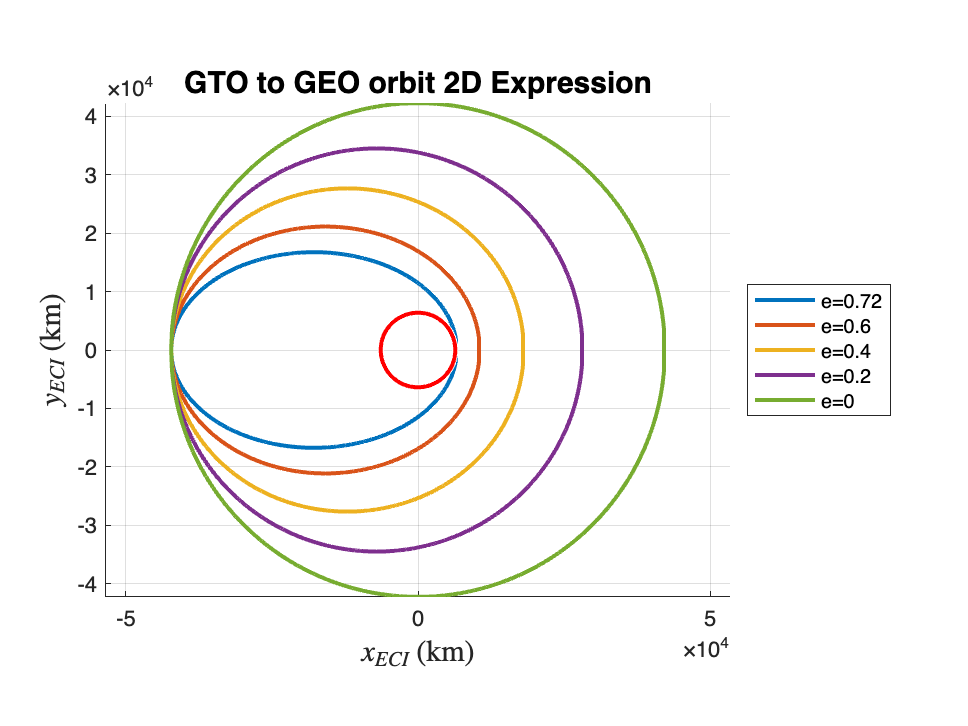

time_vector = [0:1:orbit_period, orbit_period];

figure;
hold on

% Define Orbit Propagator
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)
vel_aps(1) = norm(v(1,:));

% r(end,:)
% v(end,:)
const = SMA * (1 + ecc);

% ecc = 0.6
ecc = 0.6;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(2) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)



% ecc = 0.4
ecc = 0.4;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(3) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)

% ecc = 0.2
ecc = 0.2;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(4) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)



% ecc = 0
ecc = 1e-5;
SMA = const/(1+ecc);
orbit_period = 2*pi* sqrt(SMA^3/mu);
time_vector = [0:1:orbit_period, orbit_period];
[r0,v0]=kepler2ijk_hs(SMA,ecc,inc,RAAN,AOP,theta);
[t,y] = orbit_propagation(r0,v0,time_vector);
r = y(:,1:3);
v = y(:,4:6);
vel_aps(5) = norm(v(1,:));
plot3(r(:,1),r(:,2),r(:,3),'LineWidth',2)

% Draw Earth
viscircles([0,0],6378);


axis('equal')
view(2)
legend('e=0.72','e=0.6','e=0.4','e=0.2','e=0','Location','eastoutside')
hold off
title('GTO to GEO orbit 2D Expression','FontSize',15,'FontWeight','bold')
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15) 
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
grid on

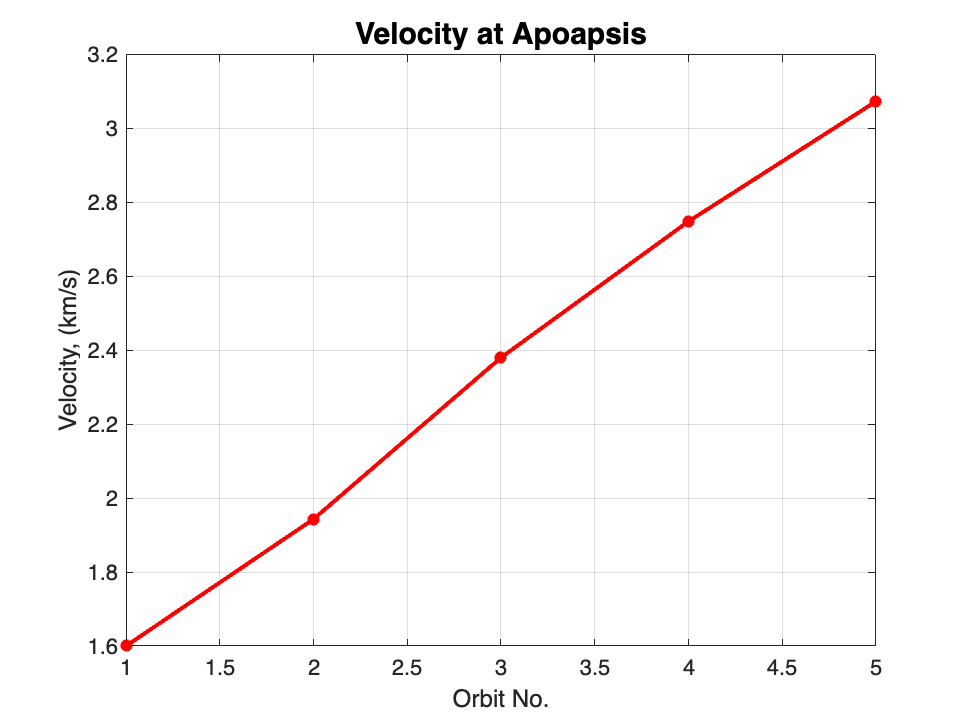



figure;

plot(1:5,vel_aps,'*-','LineWidth',2,'Color','r')
grid on
title('Velocity at Apoapsis','FontSize',15,'FontWeight','bold')
xlabel('Orbit No.')
ylabel('Velocity, (km/s)')

## Appendix 1: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end

## Appendix 2: ECI to Keplerian Converter (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;
end